# (Modified from) Estimating Transfer Function Models for a Heat Exchanger

[https://www.mathworks.com/help/ident/ug/estimating-transfer-function-models-for-a-heat-exchanger.html](https://www.mathworks.com/help/ident/ug/estimating-transfer-function-models-for-a-heat-exchanger.html)

`This script was put together for the YouTube video, "Linear System Identification | System Identification, Part 2". `

`Brian Douglas 2021`

## Collect heat exchanger data

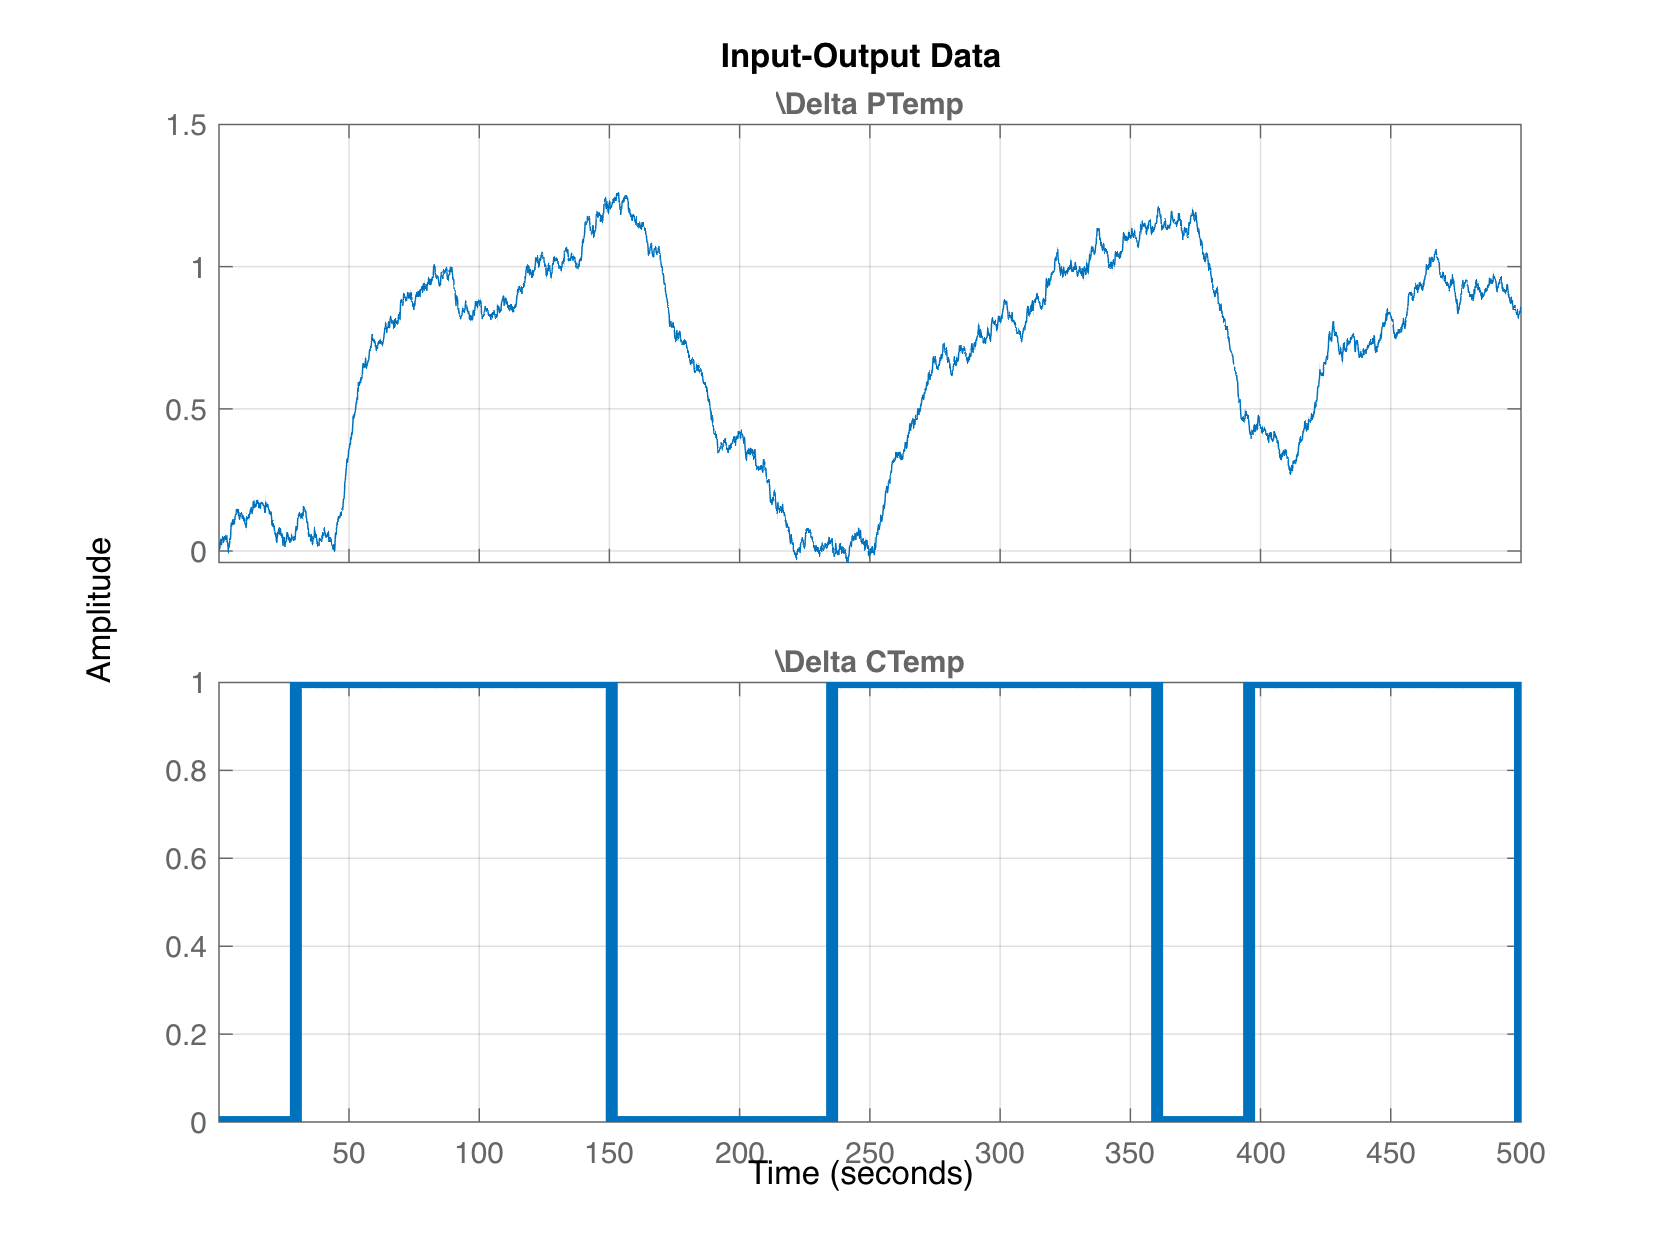

load heat_exchanger_data

Ts = 0.1; % Data sample time

% Collect the measured data using the |iddata| command and plot it.
data = iddata(output1.data,input1.data,Ts);
data.InputName  = '\Delta CTemp';
data.InputUnit  = 'C';
data.OutputName = '\Delta PTemp';
data.OutputUnit = 'C';
data.TimeUnit   = 'seconds';
plot(data)
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

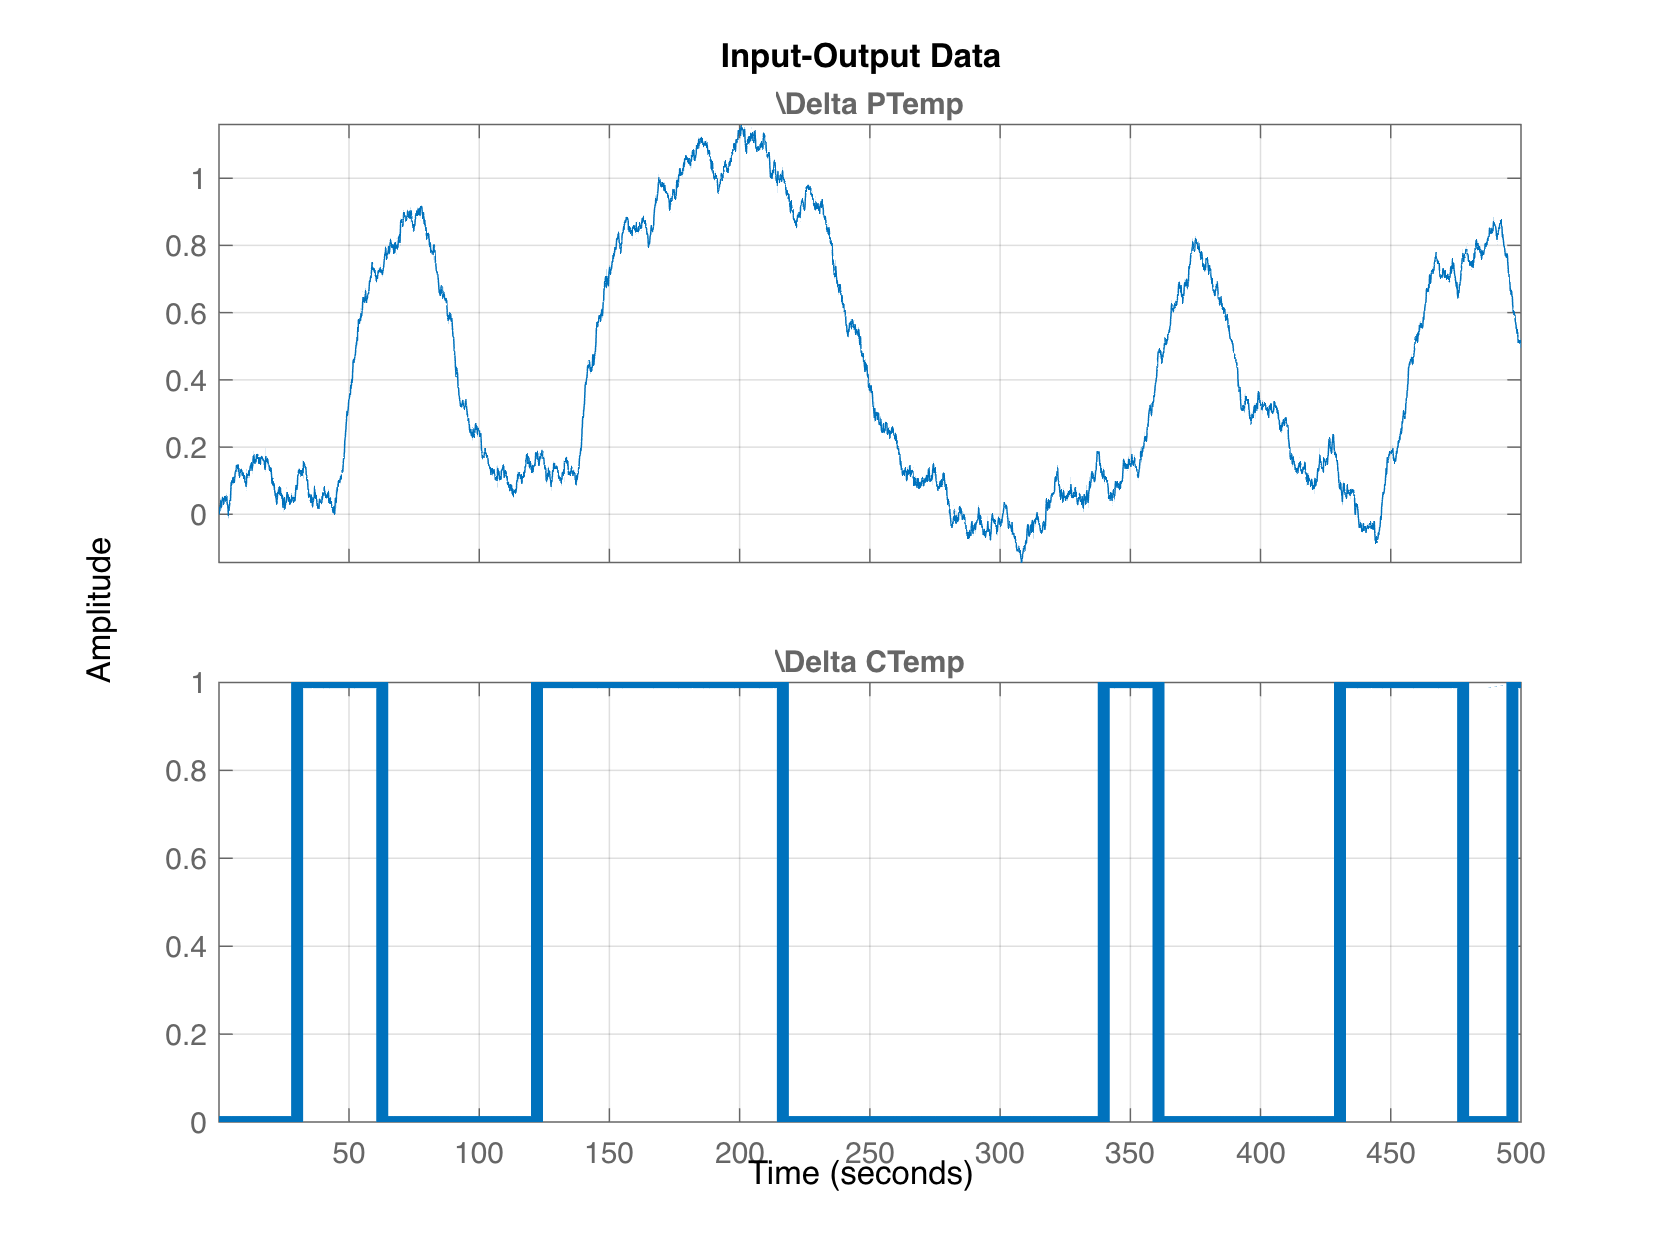


% Collect the validation data using the |iddata| command and plot it.
validation_data = iddata(output2.data,input2.data,Ts);
validation_data.InputName  = '\Delta CTemp';
validation_data.InputUnit  = 'C';
validation_data.OutputName = '\Delta PTemp';
validation_data.OutputUnit = 'C';
validation_data.TimeUnit   = 'seconds';
plot(validation_data)
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

## Identified transfer function with delay model

% Estimate the delay term
delay_samples = delayest(data, 2, 2, 0, 200);
delay_time = delay_samples * Ts

delay_time = 15.2000

sysTF = tfest(data,1,0,delay_time)

sysTF =
 
  From input "\Delta CTemp" to output "\Delta PTemp":
                   0.03919
  exp(-15.2*s) * -----------
                 s + 0.03641
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 74.4%                    
FPE: 0.008885, MSE: 0.008874                     


## Validate model

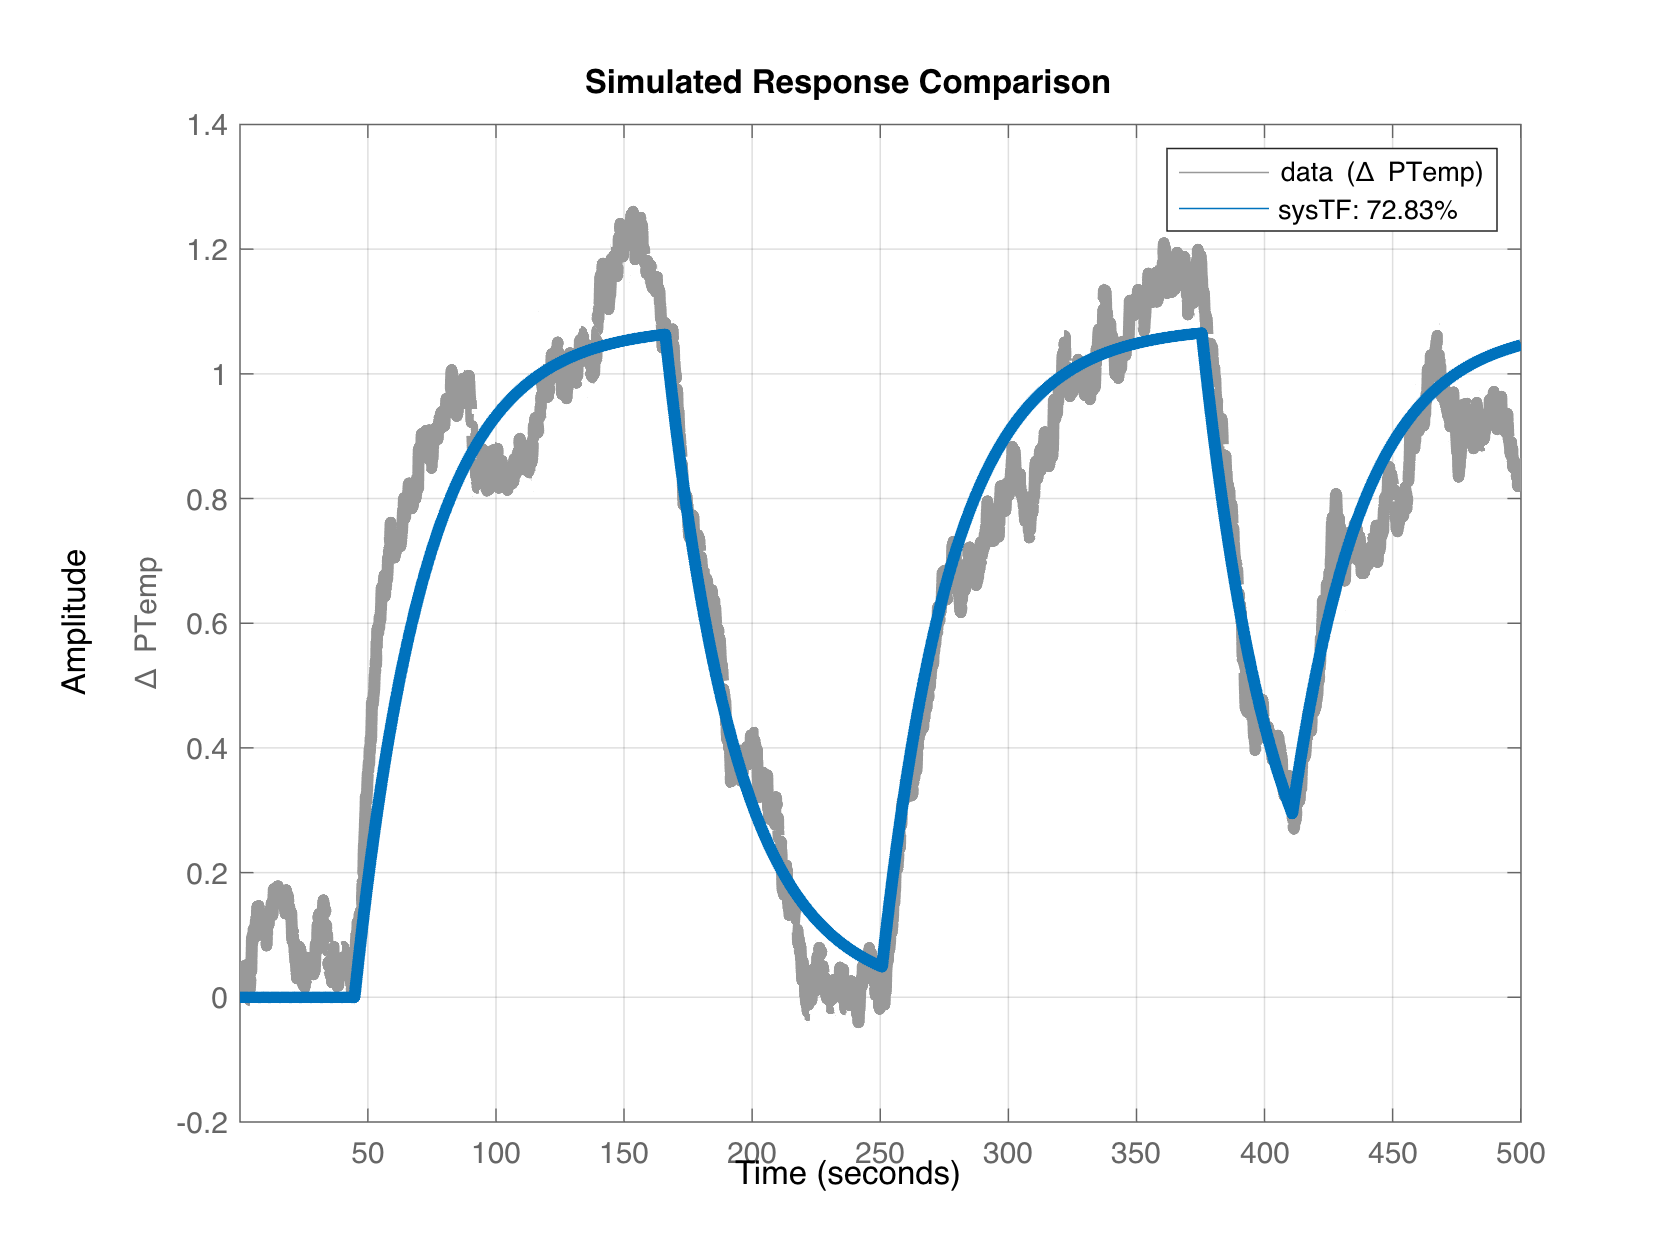

% Check the training data
opt = compareOptions;
opt.InitialCondition = 'z';
compare(data,sysTF, opt)
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

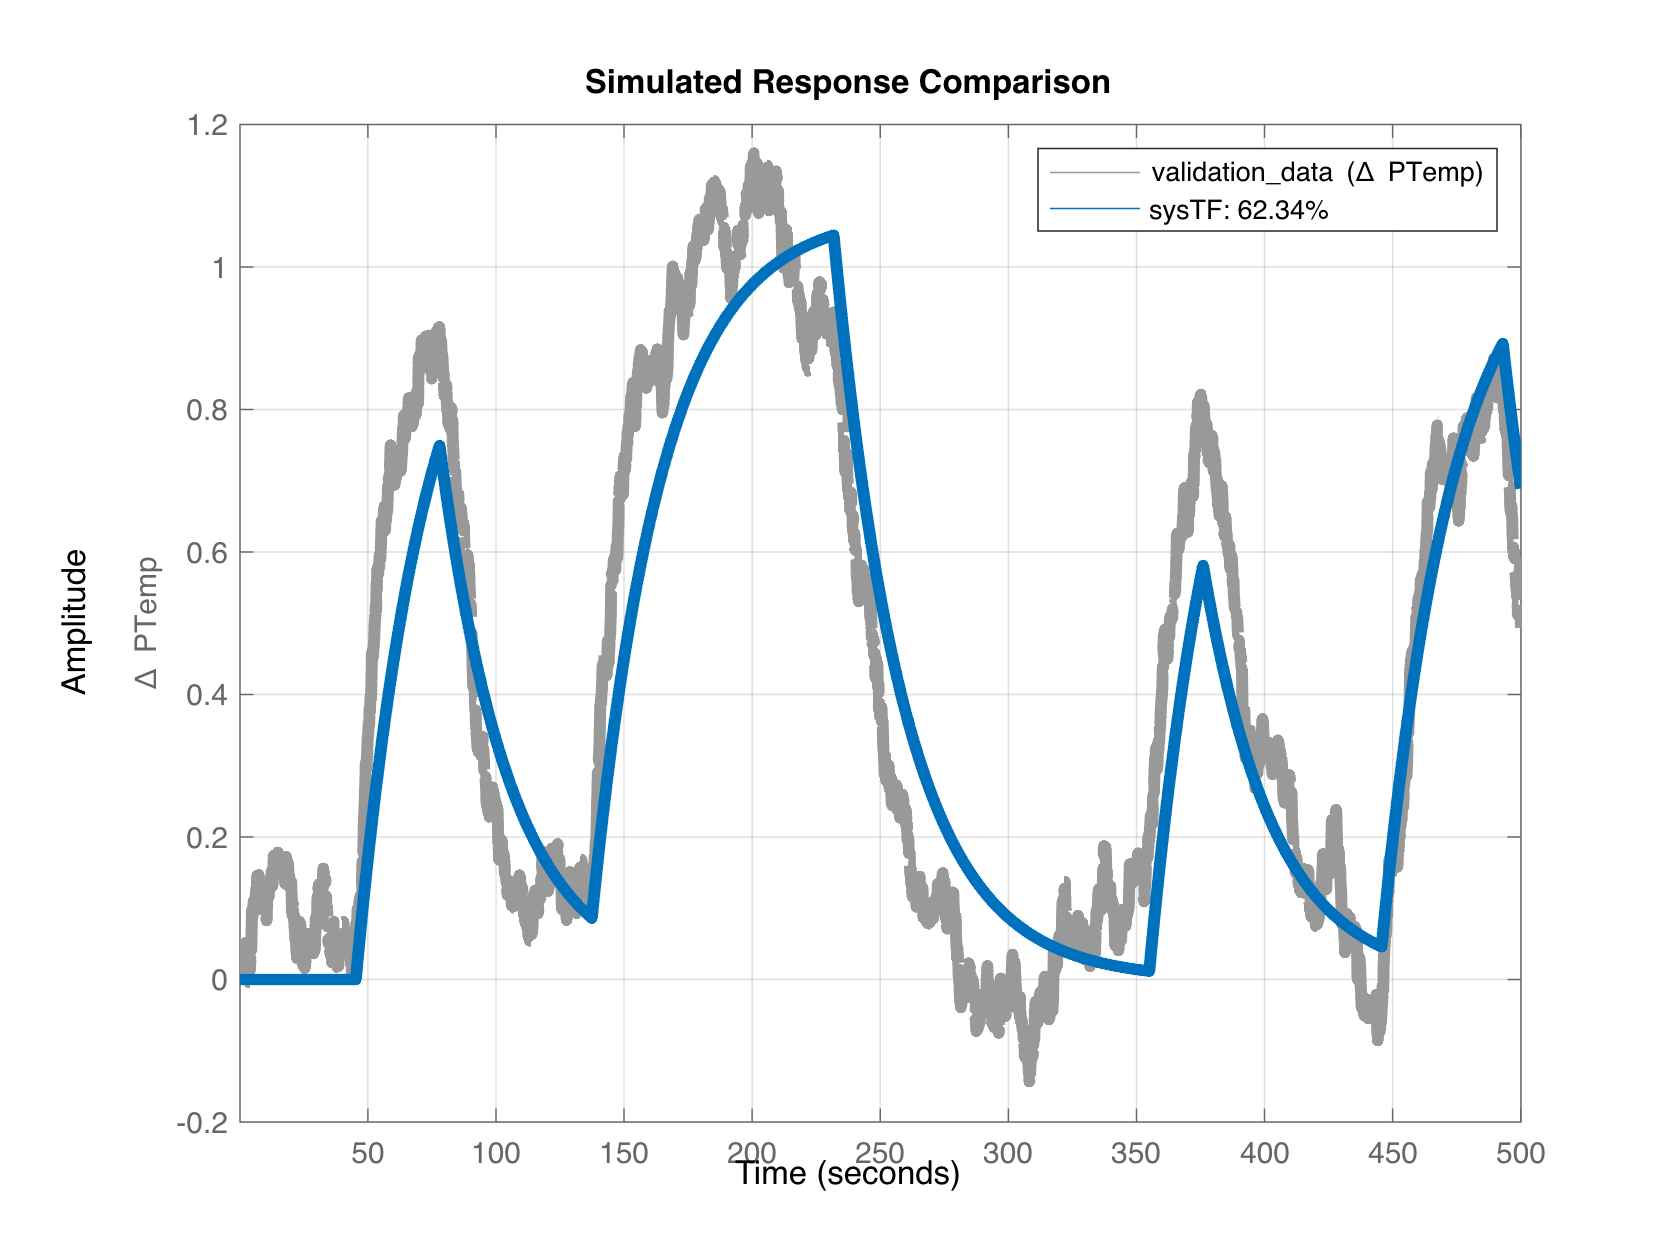

% Check the validation data
opt = compareOptions;
opt.InitialCondition = 'z';
compare(validation_data,sysTF,opt)
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

## Whiteness and Correlation tests

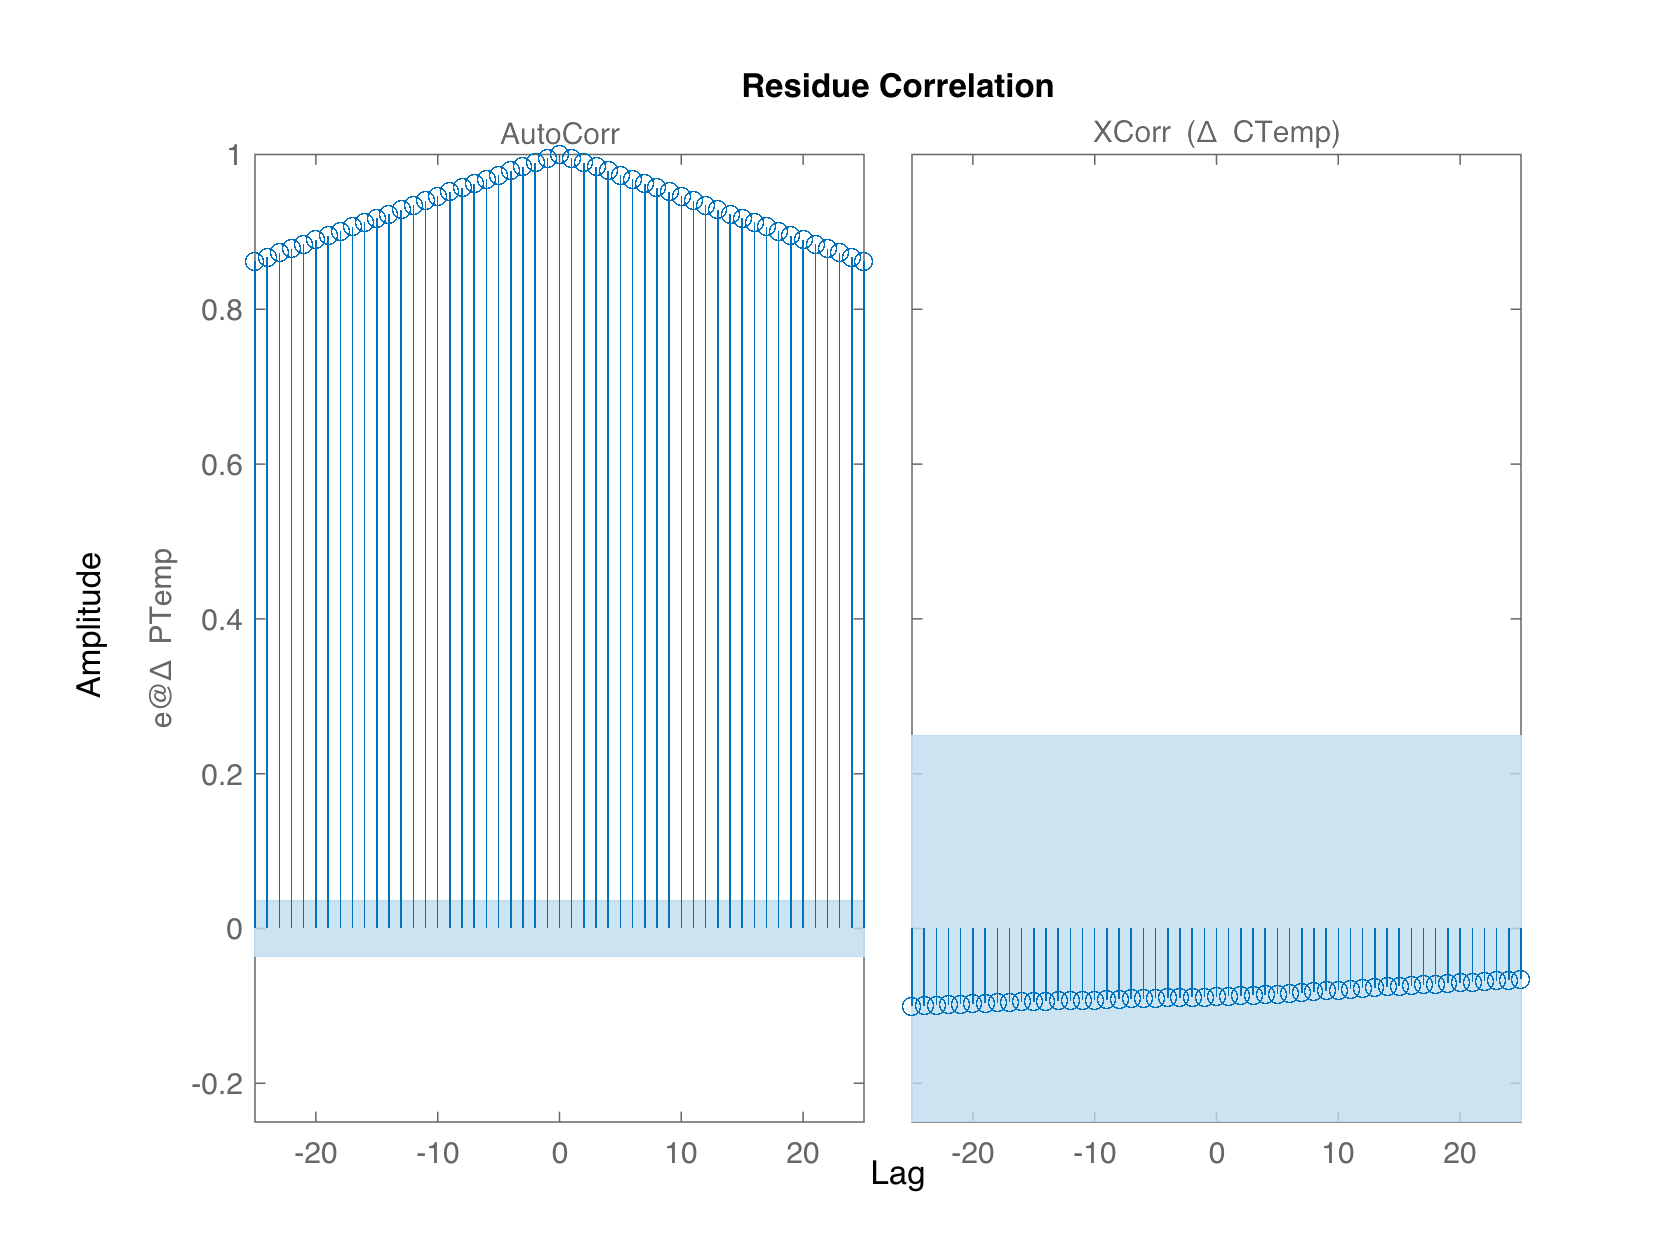

resid(sysTF,data);

## Try a new model structure: Process Model Estimation with 1st Order Disturbance Model

sysInit = idproc('P1D','TimeUnit','seconds');
sysInit.Structure.Kp.Value    = 1;
sysInit.Structure.Kp.Minimum  = 0;
sysInit.Structure.Tp1.Value   = 30;
sysInit.Structure.Tp1.Maximum = 100;
sysInit.Structure.Td.Value    = 0.2;
sysInit.Structure.Td.Minimum  = 0;
sysInit.Structure.Td.Maximum  = 20;
opt = procestOptions('DisturbanceModel','ARMA1');
sysP1D = procest(data,sysInit,opt)

sysP1D =
Process model with transfer function:                
             Kp                                      
  G(s) = ---------- * exp(-Td*s)                     
          1+Tp1*s                                    
                                                     
        Kp = 1.0594                                  
       Tp1 = 26.989                                  
        Td = 14.422                                  
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s + 10.3                                
      D(s) = s + 0.03516                             
                                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 5
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          

## Validate the model

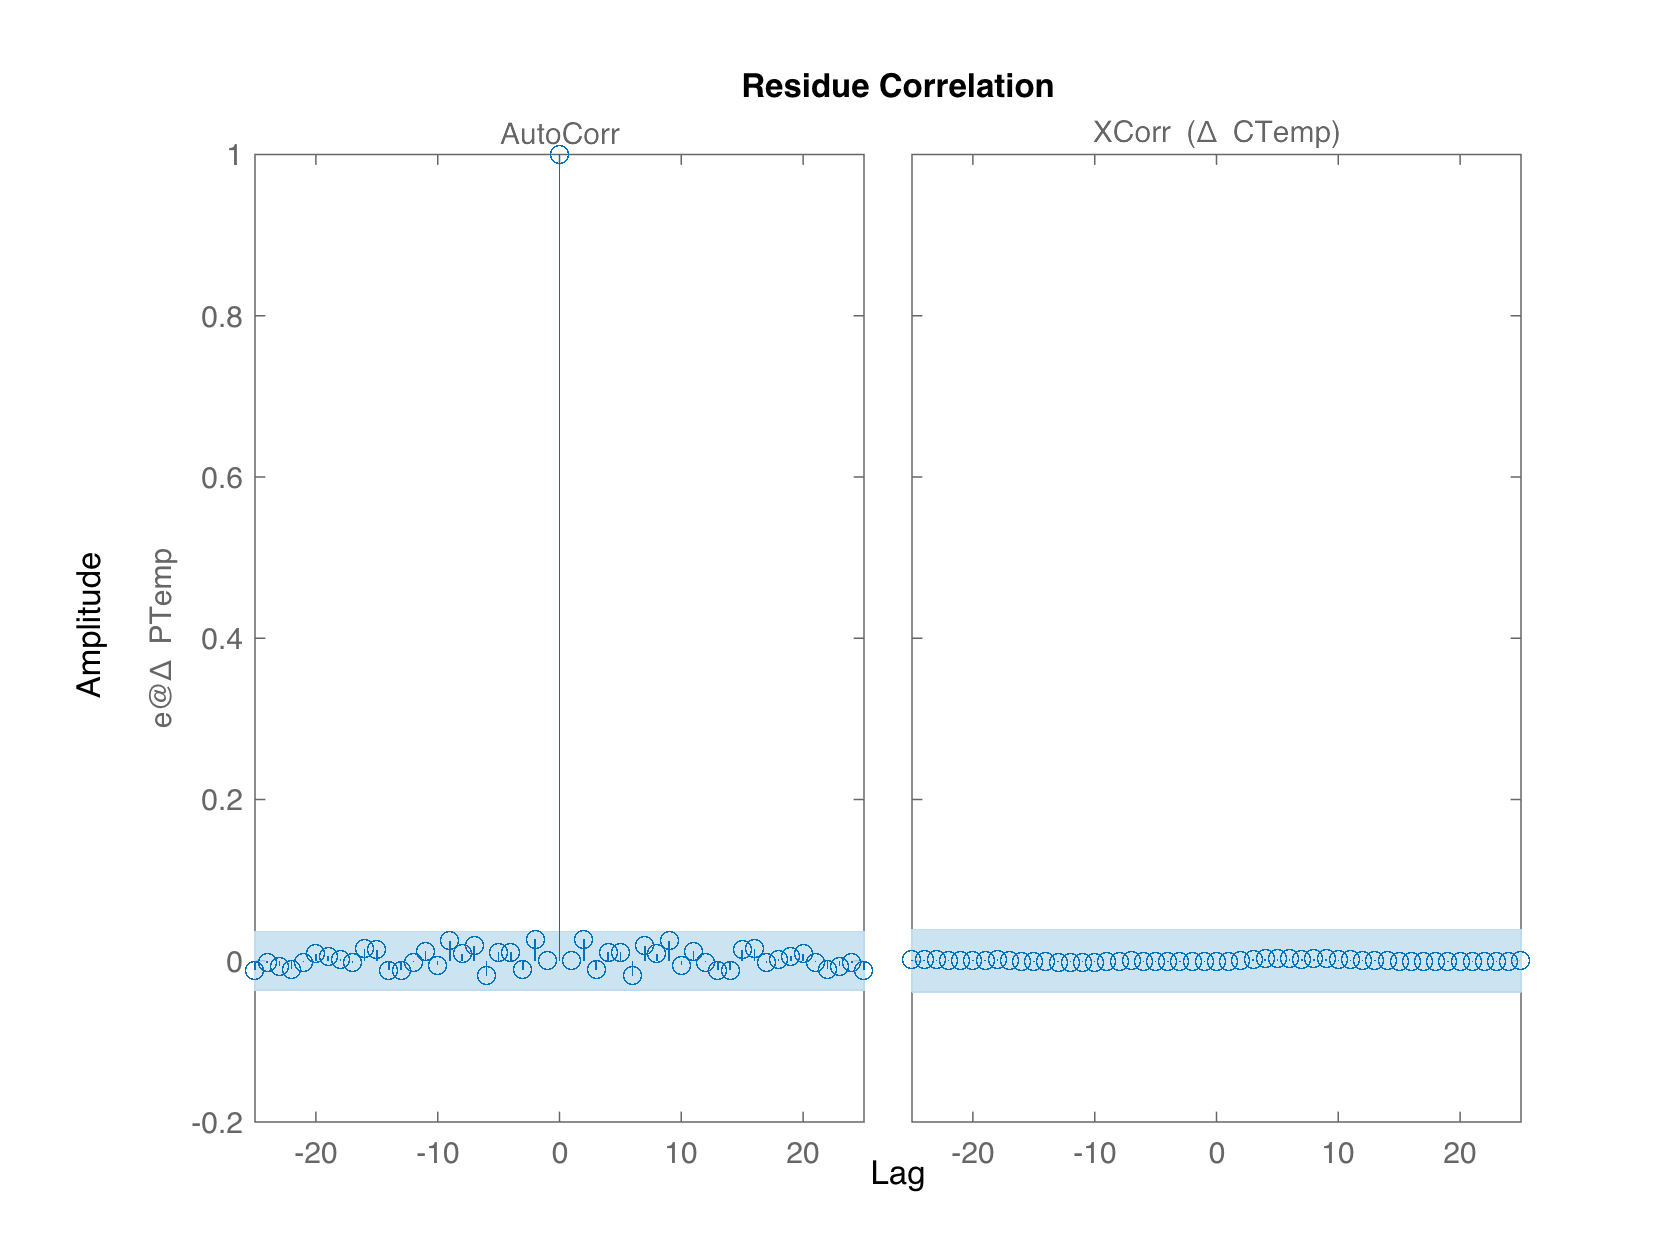

resid(sysP1D,data);

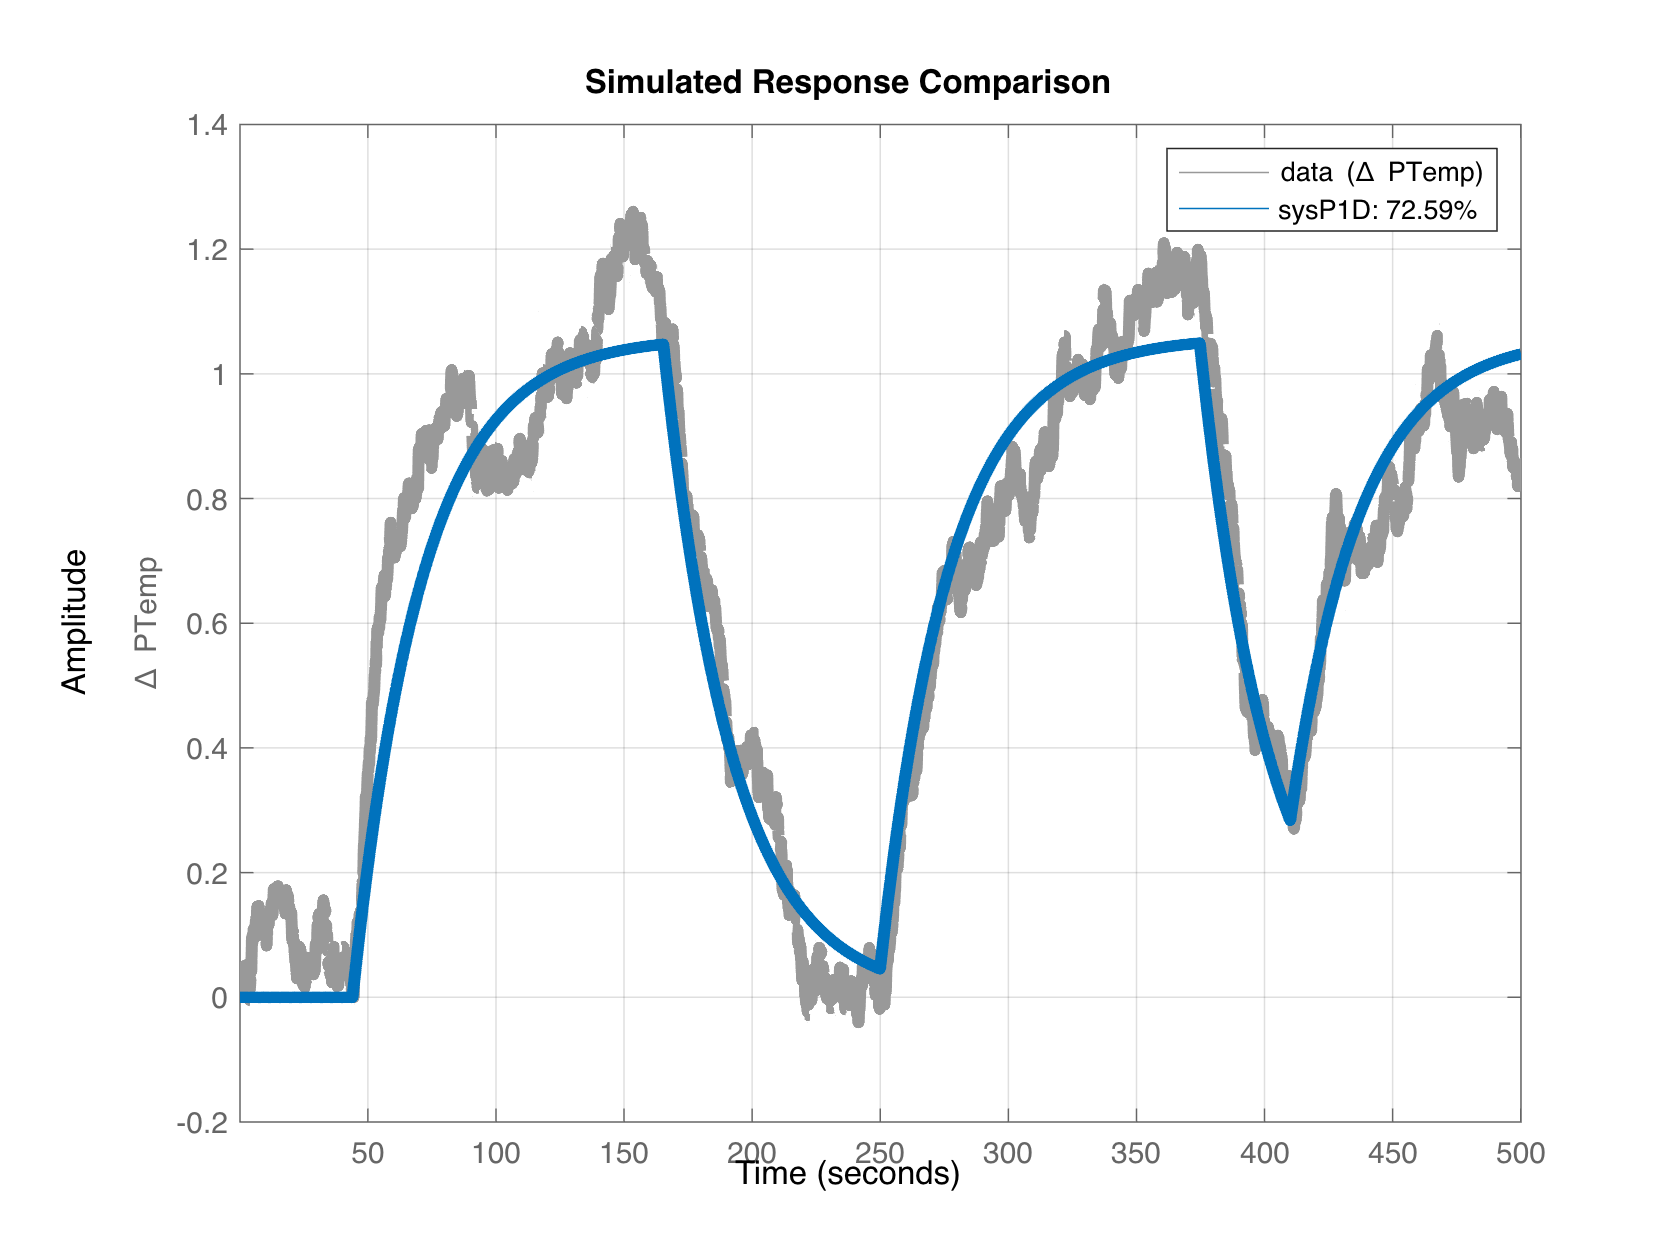

% Check the training data
opt = compareOptions;
opt.InitialCondition = 'z';
compare(data,sysP1D, opt)
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

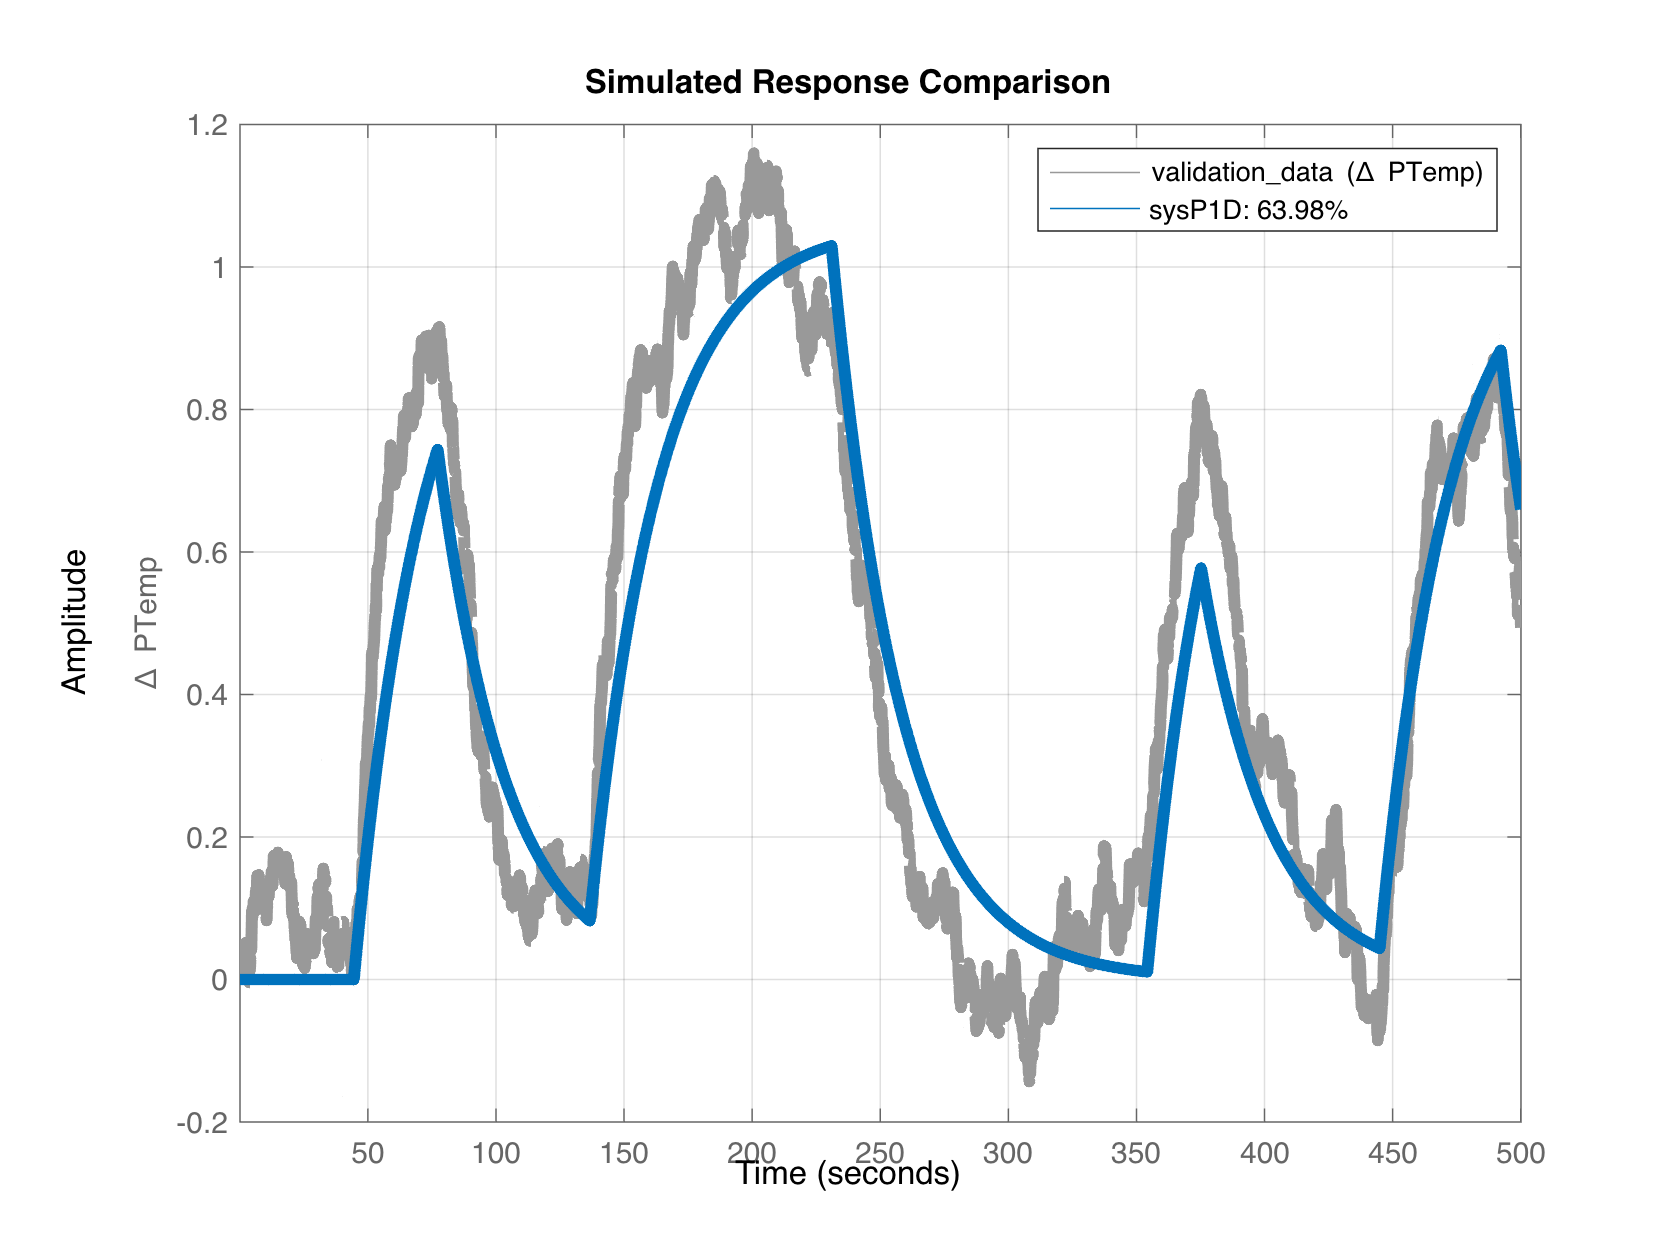

% Check the validation data
opt = compareOptions;
opt.InitialCondition = 'z';
compare(validation_data,sysP1D, opt)
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on

## Compare the transfer function and the process models

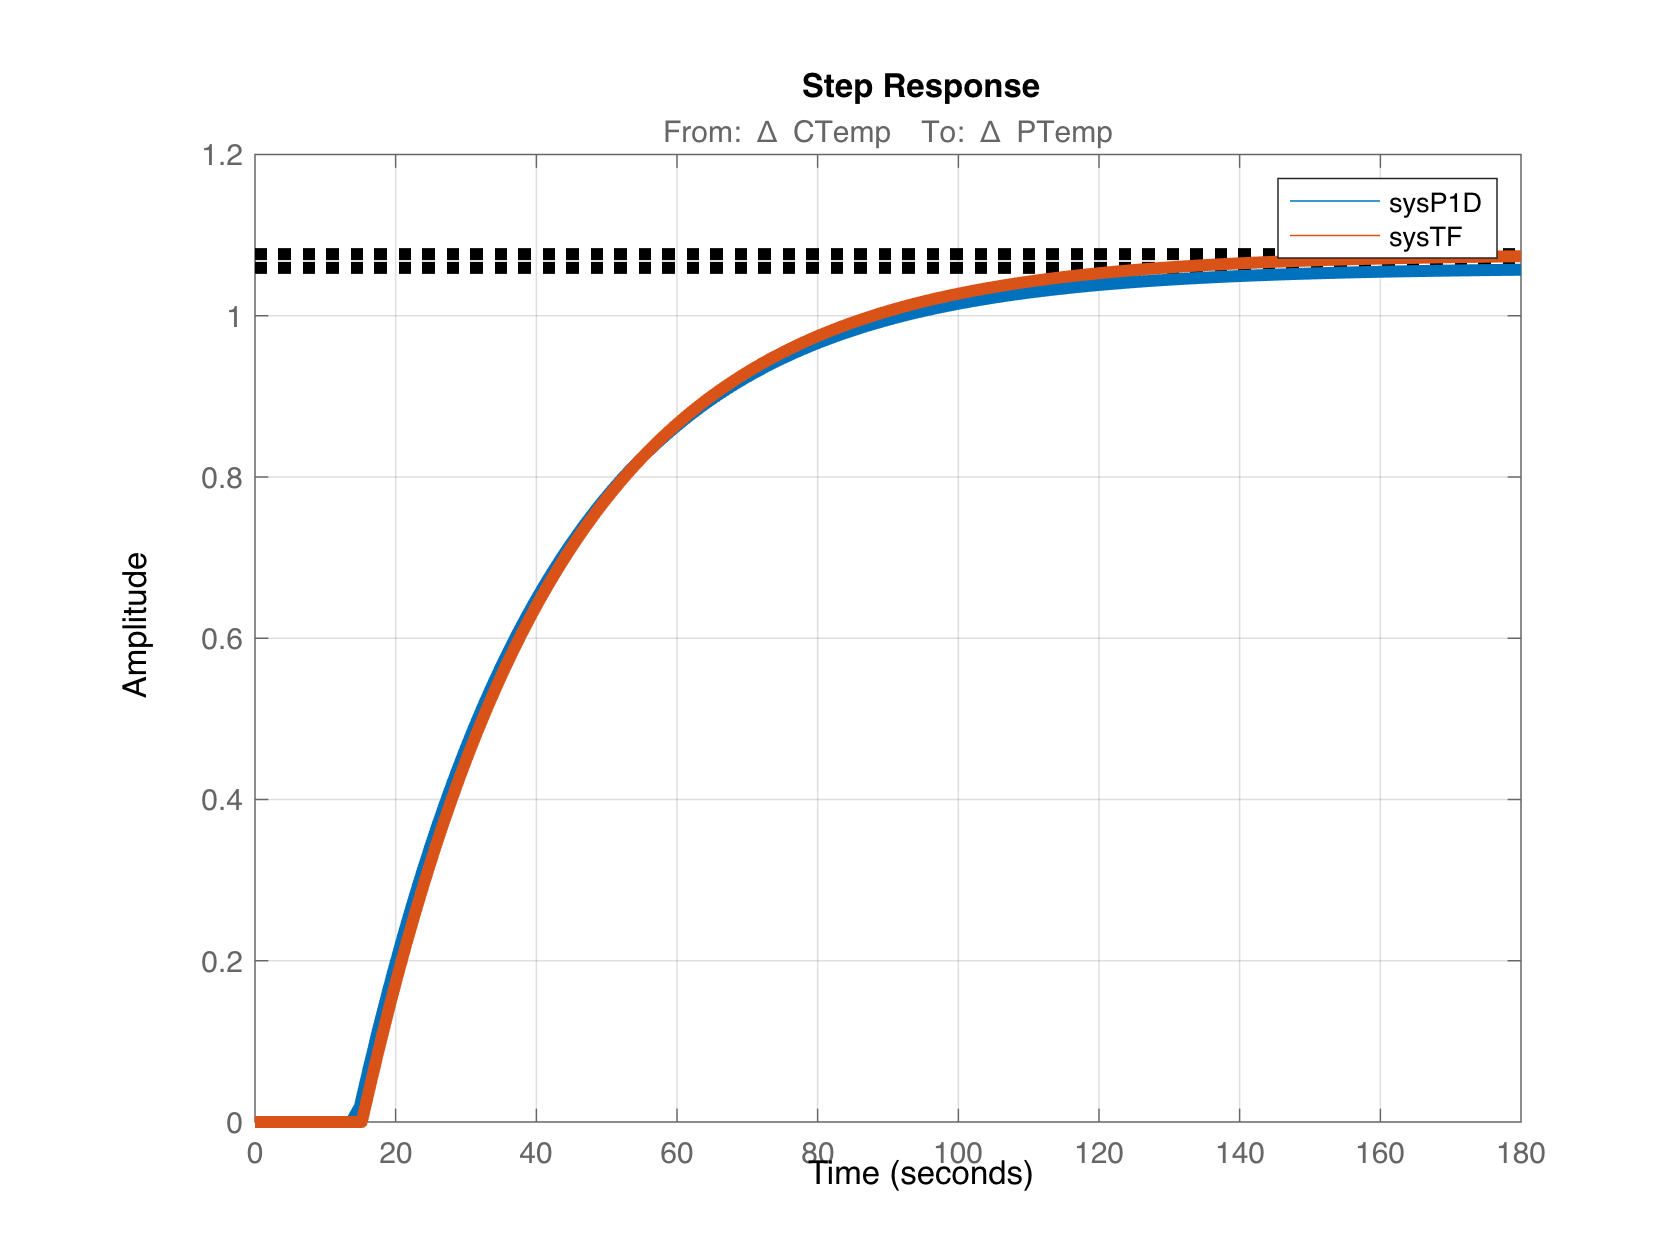

step(sysP1D,sysTF)
legend('sysP1D', 'sysTF');
set(findall(gca, 'Type', 'Line'),'LineWidth',4);
grid on